Problem 1

a

Yes, A is invertible because det(*A*)=7*10-2*(-3)+1*9=85, which does not equal 0.

b

**7**    2    1        |    2

0    3    −1      |    4        R3+(3/7)*R1 -> new R3

−3    4    2      |    6

7    2    1        |    2

0    **3**    −1      |    4        R3+(-34/21)*R2 -> new R3

0  34/7  17/7  |    48/7

7    2    1        |    2

0    **3**    −1      |    4        

0    0  85/21   |    8/21

Backsubstitution

85/21*z=8/21 -> z = 8/85 = **0.094118**

3y=4+z=4+8/85=348/85 -> y=116/85 = **1.3647**

7x=2-2y-z=2-2*116/85-8/85=-14/17 -> x = -2/17 = **-0.11765**

% b
A = [7 2 1; 0 3 -1; -3 4 2];
b = [2; 4; 6];

[Aug,x_uptrbk] = uptrbk(A, b);
Aug

Aug =     7.0000    2.0000    1.0000    2.0000
         0    4.8571    2.4286    6.8571
         0         0   -2.5000   -0.2353


x_uptrbk

x_uptrbk =    -0.1176
    1.3647
    0.0941



U = backsub(Aug, x_uptrbk);
U

U =    -0.0971
    0.2998
   -0.0376


Results confirmed!

c

A = LU

**7**    2    1             1    0    0

0    3    −1     *    0    1    0

−3    4    2           0    0    1

L:

1        0        0

0        1        0

-3/7 34/21    1 (from part b)

U:

7    2    1        |    2

0    3    −1      |    4        

0    0  85/21   |    8/21

L* U = A because the steps are reversing from part b for L

d

A = LU

Ax = c

c = [3; 4; -2]

**Ly=c**

1*y1 + 0*y2 + 0*y3 = 3

0*y1 + 1*y2 + 0*y3 = 4

-3/7*y1 + 34/21*y2 + 1*y3 = -2 

so, -3/7*3 + 34/21*4 + 1*y3 = -2 -> y3 = -151/21

therefore, **y1 = 3, y2 = 4, y3 = -151/21**

**Ux=y**

7*x1 + 2*x2 +1*x3 = 3

0*x1 + 3*x2 -1*x3 = 4

0*x1 + 0*x2 +85/21*x3 = -151/21

so, x3 = -151/85, 

so, 3*x2 -1*(-151/85) = 4 -> x2 = 63/85

so, 7*x1 + 2*(63/85) +1*(-151/85) = 3 -> x1 = 8/17

therefore, x1 = 8/17**, **x2 = 63/85**, **x3 = -151/85

y = [3, 4, -151/21]

x = [8/17, 63/85, -151/85]

y = [3; 4; -151/21]

y =     3.0000
    4.0000
   -7.1905


x = [8/17; 63/85; -151/85]

x =     0.4706
    0.7412
   -1.7765



U.*x

ans =    -0.0457
    0.2222
    0.0669


y

y =     3.0000
    4.0000
   -7.1905


%not working

Problem 2

f1 = @(x, y) x.^2 - 2*x - y - 0.5;
f2 = @(x, y) x.^2 + 4*y - 4;
df1_dx = @(x, y) 2*x - 2;
df1_dy = @(x, y) -1;
df2_dx = @(x, y) 2*x;
df2_dy = @(x, y) 4;

x0 = 0;
y0 = 0;
thresh = 1e-6;
max_iter = 1000;

% Newton-Raphson iteration
for iter = 1:max_iter
    f1_val = f1(x0, y0);
    f2_val = f2(x0, y0);
    df1_dx_val = df1_dx(x0, y0);
    df1_dy_val = df1_dy(x0, y0);
    df2_dx_val = df2_dx(x0, y0);
    df2_dy_val = df2_dy(x0, y0);

    J = [df1_dx_val, df1_dy_val; df2_dx_val, df2_dy_val];
    incr = -J\[f1_val; f2_val];
    
    x0 = x0 + incr(1);
    y0 = y0 + incr(2);
    
    if norm(incr) < thresh
        break;
    end
end

fprintf('Intersection point: x = %.6f, y = %.6f\n', x0, y0);

Intersection point: x = -0.556466, y = 0.922586


Bonus

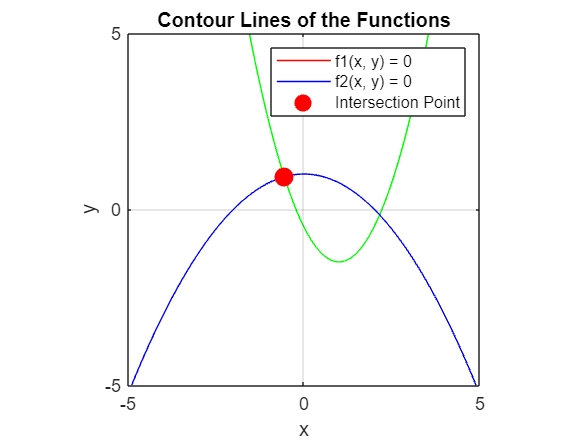

x_range = linspace(-5, 5, 100);
y_range = linspace(-5, 5, 100);

[X, Y] = meshgrid(x_range, y_range);
Z1 = f1(X, Y);
Z2 = f2(X, Y);

contour(X, Y, Z1, [0 0], 'g'); hold on;
contour(X, Y, Z2, [0 0], 'b');

plot(x0, y0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('x');
ylabel('y');
title('Contour Lines of the Functions');
legend('f1(x, y) = 0', 'f2(x, y) = 0', 'Intersection Point');
grid on;

Yes, the plot agrees with the value found in question 2.